Data Collection

clear;clc;
animal = imageDatastore('Animal',"IncludeSubfolders",true,...
    "LabelSource","foldernames");
[training, validation]=splitEachLabel(animal,0.8)

training =   ImageDatastore with properties:

                       Files: {
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Cat\download (16).jpg';
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Cat\download (17).jpg';
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Cat\download (18).jpg'
                               ... and 37 more
                              }
                     Folders: {
                              'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\Animal'
                              }
                      Labels: [Cat; Cat; Cat ... and 37 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @r

validation =   ImageDatastore with properties:

                       Files: {
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Cat\images (44).jpg';
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Cat\images (45).jpg';
                              ' ...\GitHub\Online-Matlab-Training-2020\Animal\Dog\images (46).jpg'
                               ... and 6 more
                              }
                     Folders: {
                              'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\Animal'
                              }
                      Labels: [Cat; Cat; Dog ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDat

Preprocessing Size Normalization

augTraining = augmentedImageDatastore([200 200 3],training);
augValidation =  augmentedImageDatastore([200 200 3],validation);


Layer / Architecture creation for CNN

layers = [imageInputLayer([200 200 3])
          convolution2dLayer(12,120)
          reluLayer
          maxPooling2dLayer(3,'Stride',3)
          
          fullyConnectedLayer(3)
          softmaxLayer
          classificationLayer];
      

training option

      opts = trainingOptions('adam', ...
     'ExecutionEnvironment',"gpu",...
    'MaxEpochs',30, ...
    'MiniBatchSize',10,...
    'InitialLearnRate',.0001,...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...   
    'ValidationData',augValidation);

Training

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:16 |       50.00% |       22.22% |       5.6096 |      12.3996 |      1.0000e-04 |


|      13 |          50 |       00:00:28 |       90.00% |       55.56% |       0.1890 |       7.0855 |      1.0000e-04 |


|      25 |         100 |       00:00:39 |      100.00% |       55.56% |  -0.0000e+00 |       5.8784 |      1.0000e-04 |


|      30 |         120 |       00:00:43 |      100.00% |       55.56% |  -0.0000e+00 |       5.9352 |      1.0000e-04 |
|======================================================================================================================|


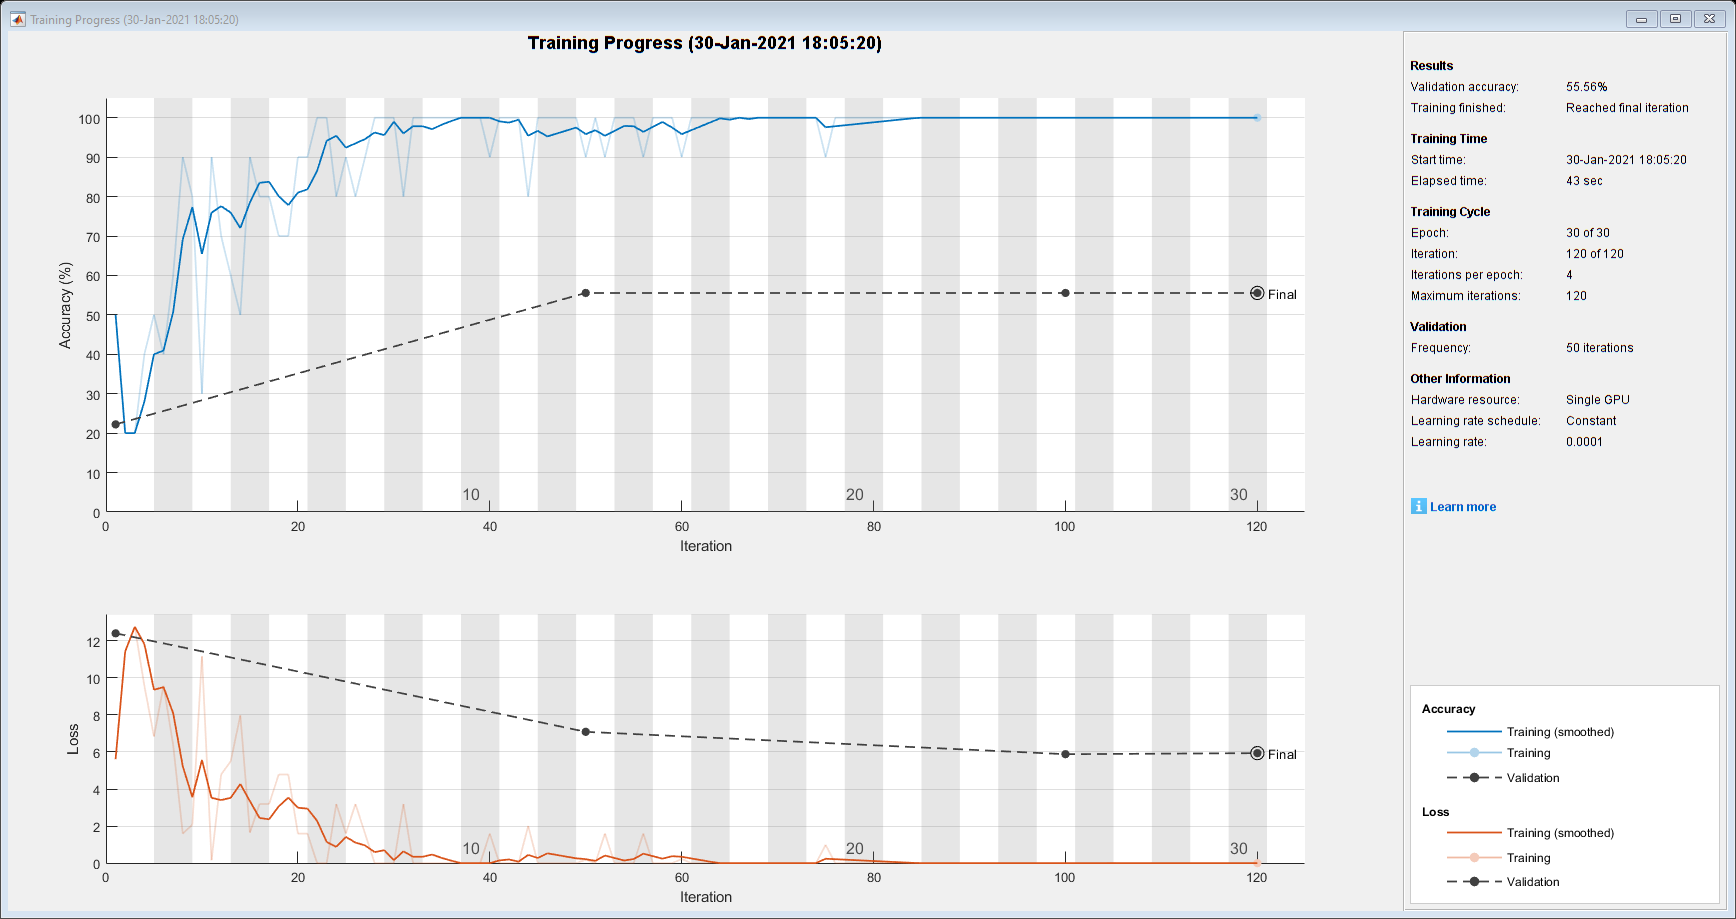

AnimalNet = trainNetwork(augTraining,layers,opts);

save AnimalNet

testdata= imageDatastore('testimage',"IncludeSubfolders",true,...
    "LabelSource","foldernames")

testdata =   ImageDatastore with properties:

                       Files: {
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (1).jpg';
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (2).jpg';
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (3).jpg'
                               ... and 6 more
                              }
                     Folders: {
                              'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage'
                              }
                      Labels: [Cat; Cat; Cat ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                

testdata.Files

ans = 9×1 cell array
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (1).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (2).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (3).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\images (49).jpg'}
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (1).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (2).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (3).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Fish\1 (1).jpg'     }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Fish\1 (2).jpg'     }


TrueResult =testdata.Labels

TrueResult = 9×1 categorical array
     Cat 
     Cat 
     Cat 
     Cat 
     Dog 
     Dog 
     Dog 
     Fish 
     Fish 


augTest = augmentedImageDatastore([200 200 3],testdata);
ypred =classify(AnimalNet,augTest)

ypred = 9×1 categorical array
     Dog 
     Fish 
     Dog 
     Fish 
     Dog 
     Dog 
     Dog 
     Cat 
     Fish 



acurracy = 100*sum(TrueResult==ypred)/length(TrueResult)

acurracy = 44.4444

# AlexNet Transfer leaning Model

Transfer Learnig Model on  AlexNet

Load data

clear;clc;
animal = imageDatastore('Animal',"IncludeSubfolders",true,...
    "LabelSource","foldernames");
animal.Labels;
[training, validation]=splitEachLabel(animal,0.8);

Preprocessing Size Normalization

augTraining = augmentedImageDatastore([227 227 3],training)

augTraining =   augmentedImageDatastore with properties:

             NumObservations: 40
                       Files: {40×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


augValidation =  augmentedImageDatastore([227 227 3],validation);

load the network

Animal = alexnet

Animal =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


Modification 

layer = Animal.Layers

layer =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0 

layer(end-2)=fullyConnectedLayer(3,'Name','FC8');
layer(end-1)=softmaxLayer;
layer(end)= classificationLayer;
layer

layer =   25x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
  

Feature = activations(Animal,augTraining,'fc7','outputAs','rows')

Feature = 40×4096 single matrix
   -8.8818    2.3330    7.2759    1.4746  -10.6424   -6.3625    0.7598   -8.5189   -7.1332   -8.7014   -6.9203   -8.5537   -7.4566   23.2584    0.2449   -0.3621   -2.9693   -2.6603   -8.2745    3.3080   -2.6574   -8.6511   -3.2534   -5.0871   -4.8556   -3.6817   -4.9535   -8.9437    0.6784   -7.1931    9.6357  -12.4031   -6.1176   -5.2608   -3.7360    0.5117   -4.4344   -2.5266   -6.0089    0.9667   -2.1429   -7.7175   -2.1702   -5.7641   -7.9093   -2.3046   -4.8324   -6.1121   -1.4386   -7.3550
   -5.5060   -2.9293    6.0321   -0.5590   -6.4372   -9.9942   -6.1717   -4.4854   -8.9242   -5.7877    0.0166   -0.3921  -10.5882    4.5806   -0.0468   -2.2640   -1.2530   -3.7321   -8.8258   -3.1324   -4.8065   -5.1121    0.0432   -8.1542   -7.2990   -6.6071   -8.6157   -4.0258   -1.6272   -9.9099    5.3304   -8.3727   -6.6039   -0.6277   -2.9769   -2.3267   -7.2307   -0.1102   -7.8648   -1.0919   -2.0417   -8.5636    3.8919   -7.6302  -11.2153   -5.8802   -9.0

Data = array2table(Feature);




option setting

 opts = trainingOptions('adam', ...
     'ExecutionEnvironment',"gpu",...
    'MaxEpochs',30, ...
    'MiniBatchSize',10,...
    'InitialLearnRate',.0001,...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...   
    'ValidationData',augValidation);


Training

% Animal= trainNetwork(augTraining,layer,opts);
% save Animal

testing

testdata= imageDatastore('testimage',"IncludeSubfolders",true,...
    "LabelSource","foldernames")

testdata =   ImageDatastore with properties:

                       Files: {
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (1).jpg';
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (2).jpg';
                              ' ...\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (3).jpg'
                               ... and 6 more
                              }
                     Folders: {
                              'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage'
                              }
                      Labels: [Cat; Cat; Cat ... and 6 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                

testdata.Files

ans = 9×1 cell array
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (1).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (2).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\3 (3).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Cat\images (49).jpg'}
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (1).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (2).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Dog\2 (3).jpg'      }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Fish\1 (1).jpg'     }
    {'C:\Users\Master\Documents\GitHub\Online-Matlab-Training-2020\testimage\Fish\1 (2).jpg'     }


TrueResult =testdata.Labels

TrueResult = 9×1 categorical array
     Cat 
     Cat 
     Cat 
     Cat 
     Dog 
     Dog 
     Dog 
     Fish 
     Fish 


augTest = augmentedImageDatastore([227 227 3],testdata);
Feature= activations(Animal,augTest,'fc7','outputAs','rows')

Feature = 9×4096 single matrix
   -3.7040   -4.0207    6.9389   -4.1380   -1.5438   -4.7077    0.7486   -4.9141   -6.9151   -3.2541   -1.2410   -5.3914   -1.5416   10.0515   -0.5029   -4.0527   -1.0019   -3.0425   -5.0785   -1.1269   -1.3731    0.4731   -3.0568   -6.2242   -2.8125   -4.9456   -4.5774   -3.8738   -0.9737   -7.0588   -0.3610   -2.3779   -4.3567   -0.5213   -1.4721   -1.2568   -4.2492   -4.2459   -8.4381    0.8620   -1.2590   -7.3023   -2.3421   -1.1881   -2.9719    1.0653   -5.8885   -0.1940   -5.8134   -6.3861
   -6.2373   -0.0359    2.9892   -0.7966   -1.3321   -2.2590   -5.5211   -4.5043  -13.8303   -3.8874   -4.4137   -6.7122   -4.4585    8.2290   -4.6291   -6.1889    2.8195    1.5846   -4.4390    5.0758   -5.4647   -5.1558    1.2419   -4.1274   -2.4923   -6.2710  -12.1737  -10.4183   -3.1278   -6.0671    3.8723   -3.1011   -1.6221   -5.6834   -6.1269    2.2819   -4.9285   -1.8441  -11.3320    1.3819   -1.0145   -7.3611   -1.3646   -6.0396   -5.0066   -2.3774   -8.22

% 
% ypred =classify(Animal,augTest)
% 
% acurracy = 100*sum(TrueResult==ypred)/length(TrueResult)